# Applications of Multiple Integrals

[⇦ Main Menu](matlab:open('MainMenu.mlx'))

To build on the fundamentals discussed in [Multiple Integrals](matlab:open('./MultipleIntegrals.mlx')), work through exercises where multiple integration appears in several different fields.

This live script is intended to be used with the code hidden. On the **View** tab of the MATLAB Toolstrip, in the **View** section, select **Hide Code**.  Alternately, select **Hide Code** using the icon   at the top right of the Live Editor pane.

 Although the code is hidden, some interactivity requires familiarity with MATLAB. If you need more instruction, consider taking [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), a free 2-hour online tutorial that teaches the essentials of MATLAB.

## Physics

A nonconducting solid occupies the region $0\leq z \leq h$ inside a right circular cylinder of radius $R$. The volume charge density is given by

$\rho(r,z) = \rho_0 \frac{z}{h}$,

where $\rho_0$ is a constant.

### Total Charge in a Cylinder

 **Exercise 1:**  Find the total charge contained in the cylinder.

a. Which coordinate system is optimal for this problem?

CheckCoordinateChoice("default",5)

b. Compute the total charge. You can give your answer in terms of `rho0, h, R,` and `pi`. 

syms R rho0 h

CheckExercise1b( )
 

## Wireless Communications

In a wireless system, each base station covers a service area. The received signal power varies with distance. Set the origin for our system at the base station. Using a simplified free-space path-loss model, we can assume that the power received is $P(r) = \frac{P_0}{r^2}$. The average power of this signal over the region $A$ is 

$\displaystyle P_{\text{avg}} = \frac{1}{\text{Area}(A)} \int\!\!\!\!\int_A P\; dA$.

### Average Received Power Over a Coverage Area

 **Exercise 2.** Compute the average power over an annular shaded region $A$ around the power station denoted as a star.

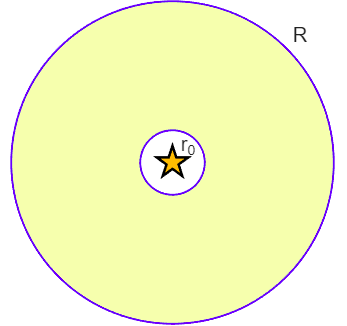

**Solution**

a. Which coordinate system is optimal for this problem?

CheckCoordinateChoice("default",6)

b. Compute the average power. You can give your answer in terms of `P0, r0, R` and `pi`. 

syms R r0 P0
CheckExercise2b( )
 

## Statics

Consider a skewed triangular prism of length $L$ that has a right‑triangle cross‑section at $z=0$ defined by $0 \leq x \leq B$ and $0\leq y \leq \frac{H}{B}x$. As $z$ increases, the cross-section is translated in the $x$-direction by an amount $kz$. The prism has a constant density $\rho_0$.

 **Exercise 3a.** Which coordinate system is optimal to compute integrals over this prism?

CheckCoordinateChoice("default",7)

 
DrawPrism(7,1,3,0.3,ShowProjection=true)

### Mass

 **Exercise 3b.** Compute the mass of the prism. You can give your answer in terms of `rho0`, `H`, `B`, `L`, `k`, and `pi`.

syms rho0 H B L k
CheckExercise3b( )
 

### Center of Mass

 **Exercise 3c.** The center of mass of an object with mass density $\rho$ and volume $V$ is found at $(\overline{x}, \overline{y}, \overline{z})$, where

$\displaystyle \overline{x} = \frac{1}{M}\int\!\!\!\!\!\int\!\!\!\!\!\int_Vx\rho\; dV$,    $\displaystyle \overline{y} = \frac{1}{M}\int\!\!\!\!\!\int\!\!\!\!\!\int_Vy\rho\; dV$,    and    $\displaystyle \overline{z} = \frac{1}{M}\int\!\!\!\!\!\int\!\!\!\!\!\int_Vz\rho\; dV$.

Compute the center of mass of the prism. You can give your answers in terms of `rho0`, `H`, `B`, `L,` `k`, and `pi`.

syms rho0 H B L k
xbar =  nan;
ybar =  nan;
zbar =  nan;
CheckExercise3c([xbar ybar zbar])
 

### Moment of Inertia

 **Exercise 3d.** Let the mass of this prism be `M`. Calculate the moment of inertia around the $z$-axis and the vertical line through the center of mass.

$\displaystyle I_z = \int\!\!\!\!\!\int\!\!\!\!\!\int_V (x^2+y^2)\rho_0\; dV$       and       $\displaystyle I_{zCM} = \int\!\!\!\!\!\int\!\!\!\!\!\int_V \left((x-\overline{x})^2+(y-\overline{y})^2\right)\rho_0\; dV.$

You can leave your answer in terms of `M`, `B`, `L`, `H`, and `k`.

DrawPrism(7,1,3,0.3,ShowInertiaAxis = true)

syms M H B L k
Iz =  NaN;    % M*(B^2/2+2*B*L*k/3+H^2/6+L^2*k^2/3)
IzCM =  NaN;  % M*(B^2/18+H^2/18+L^2*k^2/12)
 
CheckExercise3d(Iz,"z")
CheckExercise3d(IzCM,"CM")

[⇦ Main Menu](matlab:open('MainMenu.mlx'))

## Local Helper Functions

If you want to see the details of the code, select the **View** tab and switch to **Output Inline**. Alternately, select **Output inline** using the icon   at the top right of the Live Editor pane.

function CheckCoordinateChoice(opt,prob)
arguments
    opt {mustBeMember(opt,["default" "Polar" "Cartesian" "Cylindrical" "Spherical"])}
    prob
end
if opt == "default"
    disp("Please try this problem.")
    return
end

switch prob
    case 4
        CorrectAns = "Spherical";
    case 5
        CorrectAns = "Cylindrical";
    case 6
        CorrectAns = "Polar";
    case 7
        CorrectAns = "Cartesian";
end
AnsIsCorrect = opt == CorrectAns;

if AnsIsCorrect
    disp("Correct!")
    switch opt
        case "Polar"
            disp("This 2D integral has rotational symmetry and works well in polar coordinates.")
        case "Cartesian"
            disp("This integral works well in Cartesian coordinates.")
        case "Cylindrical"
            disp("This integral has cylindrical symmetries.")
        case "Spherical"
            disp("This integral simplifies elegantly in spherical coordinates.")
    end
else
    disp("No, " + opt + " is not the best choice.")
    switch opt
        case "Polar"
            disp("What is the dimension of this integral?")
        case "Cartesian"
            disp("I don't want to work with all those square roots!")
            disp("Are there any symmetries to take advantage of?")
        case "Cylindrical"
            if CorrectAns == "Spherical"
                disp("Yes, there is x-y symmetry to this figure, but that still leaves square roots.")
                disp("Is there any other symmetry?")
            elseif CorrectAns == "Polar"
                disp("What is the dimension of this integral?")
            elseif CorrectAns == "Cartesian"
                disp("Are the region boundaries curves or straight lines?")
            else
                disp("What else have you considered?")
            end
        case "Spherical"
            if CorrectAns == "Cartesian"
                disp("Are the region boundaries curves or straight lines?")
            else
                disp("What symmetries appear in this problem?")
            end
        otherwise
            error("Unexpected option:" + opt)
    end
end
end

function CheckExercise1b(MyAns)
arguments
    MyAns = NaN;
end

if isnan(MyAns)
    disp("That is the default value. Please solve the problem.")
    return
end

syms R rho0 h r z theta
% Compute the total charge contained in the cylinder using the volume charge density
Q = int(int(int(rho0 * z/h * r, r, 0, R), z, 0, h), theta, 0, 2*pi);

if isAlways(Q==MyAns,"Unknown","false")
    disp("Correct!")
    displayFormula(['"The total charge Q is "' "int(int(int(rho0 * z/h * r, r, 0, R), z, 0, h), theta, 0, 2*pi)==Q" '"."'])
else
    disp("No, that is incorrect.")
    Qnor = int(int(int(rho0 * z/h, r, 0, R), z, 0, h), theta, 0, 2*pi);
    Qdouble = int(int(int(rho0 * z/h * r, r, -R, R), z, 0, h), theta, 0, 2*pi);
    Qhalfcircle = int(int(int(rho0 * z/h * r, r, 0, R), z, 0, h), theta, 0, pi);
    if isAlways(MyAns == Qnor,"Unknown","false")
        syms dV dr dz %#ok<NASGU>
        displayFormula(['"Did you forget "' "dV == r*dr*d*theta*dz" '"?"'])
    elseif isAlways(MyAns == Qdouble,"Unknown","false")
        displayFormula('"Did you remember that the lower bound for each integral is 0?"')
    elseif isAlways(MyAns == Qhalfcircle,"Unknown","false")
        displayFormula(['"Did you remember that the angular bounds are "' "0 <= theta" '" and "' "theta <= 2*pi" '"?"'])
    else
        disp("Please check your integral and try again.")
    end
end
end

function CheckExercise2b(MyAns)
arguments
    MyAns = NaN;
end
if isnan(MyAns)
    disp("That is the default value. Please solve the problem.")
    return
end
syms R r0 P0 theta r
assume(R>r0>0)
A = int(int(r,r,r0,R),theta,0,2*pi);
P = int(int(P0/r,r,r0,R),theta,0,2*pi)/A;

if isAlways(MyAns == P,"Unknown","false")
    disp("Correct!")
    displayFormula(['"The area of the annulus is "' "int(int(r,r,r0,R),theta,0,2*pi) == A" '"."'])
    displayFormula(['"The average power is "' "int(int(P0/r^2*r,r,r0,R),theta,0,2*pi)/A == MyAns" '"."'])
else
    disp("That is not correct.")
    % Compute several potential wrong approaches to check for
    Pnor = int(int(P0/r^2,r,r0,R),theta,0,2*pi)/A;
    PnoA = int(int(P0/r,r,r0,R),theta,0,2*pi);
    PnoAnor = int(int(P0/r^2,r,r0,R),theta,0,2*pi);
    if isAlways(MyAns == Pnor,"Unknown","false")
        syms dA dr d %#ok<NASGU>
        displayFormula(['"Did you forget "' "dA == r*dr*d*theta" '"?"'])
    elseif isAlways(MyAns == PnoA,"Unknown","false")
        displayFormula('"Did you forget to average over the area?"')
    elseif isAlways(MyAns == PnoAnor,"Unknown","false")
        syms dA dr d %#ok<NASGU>
        displayFormula(['"Did you forget "' "dA == r*dr*d*theta" '"?"'])
        displayFormula('"Did you forget to average over the area?"')
    else
        displayFormula('"Please check your integral and try again."')
    end
end
end

function DrawPrism(L,H,B,k,opts)
arguments
    L = 7
    H = 1
    B = 3
    k = 0.3
    opts.ShowProjection = false
    opts.ShowCenterOfMass = false
    opts.ShowInertiaAxis = false
    opts.ShowInertiaCM = false
end
% Plot skewed triangular prism
% Define grid in (x,y,z) for prism surfaces
zv = linspace(0,L,30);
% Triangular cross-section corners at each z: (kz,y,z), (kz+B,y,z) careful:
% At given z, x runs from k*z to B + k*z, and y from 0 to (H/B)*(x-k*z).
% Represent three faces: bottom (y=0), slanted hypotenuse y=(H/B)*(x-kz), front and back x=kz and x=B+kz
% Create surface for hypotenuse: parametrize by s in [0,1] along x range and z
sz = zv;
sx = linspace(0,1,50);
[SS,ZZ] = meshgrid(sx,sz); % SS across x fraction, ZZ across z
Xh = (k*ZZ) + SS.*B;               % x = kz + s*B
Yh = (H/B)*(Xh - k*ZZ);           % y = (H/B)*(x-kz) = (H/B)*s*B = H*s
Zh = ZZ;

% Bottom face y=0 (rectangle in x-z)
[XXb,ZZb] = meshgrid(linspace(0,1,2),zv);
Xb = k*ZZb + XXb*B;
Yb = zeros(size(Xb));
Zb = ZZb;

% Vertical face at x = B + k*z (right face)
[YYr,ZZr] = meshgrid(linspace(0,1,30),zv);
Xr = B + k*ZZr + 0*YYr;
Yr = (H*YYr);
Zr = ZZr;

figure
hold on
surf(Xh,Yh,Zh,FaceColor=[0.8 0.3 0.3],EdgeColor="none",FaceAlpha=0.2) % hypotenuse
surf(Xb,Yb,Zb,FaceColor=[0.3 0.6 0.9],EdgeColor="none",FaceAlpha=0.2) % bottom
surf(Xr,Yr,Zr,FaceColor=[0.9 0.7 0.3],EdgeColor="none",FaceAlpha=0.2) % right
if opts.ShowProjection
    plot3([k*L+B k*L+B],[0 0],[0 L],"--",SeriesIndex=2,LineWidth=2)
    plot3([k*L k*L],[0 0],[0 L],"--",SeriesIndex=2,LineWidth=2)
end
if opts.ShowCenterOfMass
    xbar = 2*B/3+L*k/2;
    ybar = H/3;
    zbar = L/2;
    scatter3(xbar,ybar,zbar,"filled")
end
if opts.ShowInertiaAxis
    plot3([0 0],[0 0],[0 L],"--",SeriesIndex=2,LineWidth=2)
end
if opts.ShowInertiaCM
    xbar = 2*B/3+L*k/2;
    ybar = H/3;
    plot3([xbar xbar],[ybar ybar],[0 L],"--",SeriesIndex=2,LineWidth=2)
end
fill3([0 B B 0],[0 0 H 0],[0 0 0 0],[0.3 0.9 0.5],EdgeColor="none",FaceAlpha=0.2)
fill3([k*L B+k*L B+k*L k*L],[0 0 H 0],[L L L L],[0.3 0.9 0.5],EdgeColor="none",FaceAlpha=0.2)

% Edges for clarity
% Outline at z=0
x0 = [0 B B 0 0];
y0 = [0 0 H 0 0];
z0 = zeros(size(x0));
plot3(x0,y0,z0,SeriesIndex="none",LineWidth=1.5)
% Outline at z=L
xL = k*L + [0 B B 0 0];
yL = [0 0 H 0 0];
zL = L*ones(size(xL));
plot3(xL,yL,zL,SeriesIndex="none",LineWidth=1.5)

% Axes labels and view
axis equal
xlabel("x"); ylabel("y"); zlabel("z");
zlim([0 L+0.1])
ylim([0 H+0.1])
xlim([0 k*L+B+0.1])
xticks([0 k*L B k*L+B])
yticks([0 H])
zticks([0 L])
xticklabels(["0" "k*L" "B" "k*L+B"])
yticklabels(["0" "H"])
zticklabels(["0" "L"])
view([6.82 40.08])
camlight headlight
lighting gouraud

hold off
end

function CheckExercise3b(MyM)
arguments
    MyM = NaN;
end
if any(isnan(MyM))
    disp("This is the default value.")
    disp("Please enter a computed value in terms of rho0, H, B, L, k, and pi.")
    return
end
syms rho0 H B L k x y z
Mans = int(int(int(rho0,y,0,H/B*(x-k*z)),x,k*z,B+k*z),z,0,L);

if isAlways(MyM==Mans,"Unknown","false")
    disp("Correct!")
    displayFormula(['"The total mass is "' "int(int(int(rho0,y,0,H/B*(x-k*z)),x,k*z,B+k*z),z,0,L)==Mans" '"."'])
else
    disp("No, that is incorrect.")
    if isAlways(MyM == rho0*H*B*L,"Unknown","false")
        disp("Did you properly incorporate the skew in your bounds?")
    elseif isAlways(MyM == H*B*L/2,"Unknown","false")
        disp("Did you remember to include the mass density?")
    else
        disp("Please try again.")
    end
end
end

function CheckExercise3c(MyCM)
arguments
    MyCM = NaN;
end
if any(isnan(MyCM))
    disp("This is the default value.")
    disp("Please enter a computed value in terms of rho0, H, B, L, k, and pi.")
    return
end

syms rho0 H B L k x y z
M = rho0/2*H*B*L;
xbarSoln = int(int(int(x*rho0,y,0,H/B*(x-k*z)),x,k*z,B+k*z),z,0,L)/M;
ybarSoln = int(int(int(y*rho0,y,0,H/B*(x-k*z)),x,k*z,B+k*z),z,0,L)/M;
zbarSoln = int(int(int(z*rho0,y,0,H/B*(x-k*z)),x,k*z,B+k*z),z,0,L)/M;

SolnOpts = isAlways(MyCM==[xbarSoln ybarSoln zbarSoln],"Unknown","false");
if all(SolnOpts)
    disp("Correct!")
    syms xbar ybar zbar %#ok<NASGU>
    displayFormula(['"The center of mass is "' "xbar == xbarSoln" '", "' "ybar == ybarSoln" '", and "' "zbar == zbarSoln" '"."'])
    DrawPrism(7,1,3,0.3,ShowCenterOfMass=true)
else
    disp("Incorrect.")
    if any(isAlways(MyCM == [xbarSoln ybarSoln zbarSoln]*M,"Unknown","false"))
        displayFormula('"Did you forget to divide by the mass?"')
    elseif any(SolnOpts)
        coords = ["xbar" "ybar" "zbar"];
        disp("Please check your work for the " + coords(~SolnOpts) + " calculation.")
    else
        disp("Please try again.")
    end
end
end

function CheckExercise3d(MyM,MyAxis)
arguments
    MyM = NaN
    MyAxis = "z"
end
if isnan(MyM)
    disp("This is the default value.")
    disp("Please enter a computed value in terms of rho0, H, B, L, k, and M.")
    return
end
syms rho0 H B L k x y z M
MyMass = int(int(int(rho0,y,0,H/B*(x-k*z)),x,k*z,B+k*z),z,0,L);
MyI = subs(MyM,M,MyMass);
xbar = int(int(int(x*rho0,y,0,H/B*(x-k*z)),x,k*z,B+k*z),z,0,L)/MyMass;
ybar = int(int(int(y*rho0,y,0,H/B*(x-k*z)),x,k*z,B+k*z),z,0,L)/MyMass;
if MyAxis == "z"
    ISoln =  int(int(int((x^2+y^2)*rho0,y,0,H/B*(x-k*z)),x,k*z,B+k*z),z,0,L);
    IWrong1 = int(int(int(((x-xbar)^2+(y-ybar)^2)*rho0,y,0,H/B*(x-k*z)),x,k*z,B+k*z),z,0,L);
    msg = '"The moment of inertia around the z-axis is "';
elseif MyAxis == "CM"
    ISoln = int(int(int(((x-xbar)^2+(y-ybar)^2)*rho0,y,0,H/B*(x-k*z)),x,k*z,B+k*z),z,0,L);
    IWrong1 = int(int(int((x^2+y^2)*rho0,y,0,H/B*(x-k*z)),x,k*z,B+k*z),z,0,L);
    msg = '"The moment of inertia vertically around the center of mass is "';
end
IWrong2 = int(int(int((x^2+z^2)*rho0,y,0,H/B*(x-k*z)),x,k*z,B+k*z),z,0,L);
IWrong3 = int(int(int((y^2+z^2)*rho0,y,0,H/B*(x-k*z)),x,k*z,B+k*z),z,0,L);

if isAlways(MyI==ISoln,"Unknown","false")
    disp("Correct!")
    displayFormula([msg "MyM" '"."'])
else
    disp("No, that is incorrect.")
    if isAlways(MyI == IWrong1,"Unknown","false")
        disp("It looks like you computed around the wrong axis. Please try again.")
    elseif isAlways(MyI == IWrong2,"Unknown","false")
        disp("That is the moment around the y-axis! Please try again.")
    elseif isAlways(MyI == IWrong3,"Unknown","false")
        disp("That is the moment around the x-axis! Please try again.")
    elseif isAlways(MyI==ISoln/MyMass,"Unknown","false")
        disp("You forgot to include the mass factor.")
    else
        disp("Please try again.")
    end
end
end

function GraphicHandle = DrawSlice(XData,YData,ZData,SliceData,GraphicHandle,idx)
if idx == 2
    tmpX = XData(SliceData);
    tmpY = YData(SliceData);
    tmpZ = ZData(SliceData);
else
    tmpX = XData;
    tmpY = YData;
    tmpZ = ZData;
    tmpX(~SliceData) = nan;
    tmpY(~SliceData) = nan;
    tmpZ(~SliceData) = nan;
end
set(GraphicHandle.Children(idx), "XData", tmpX, "YData", tmpY, "ZData", tmpZ);
end

function Slice = MakeSlices(CapData,StemData,PumpkinData,CavityData,Slice)
Slice.Cap = CapData > Slice.Endpoints(1) & CapData < Slice.Endpoints(2);
Slice.Stem = StemData > Slice.Endpoints(1) & StemData < Slice.Endpoints(2);
Slice.Pumpkin = PumpkinData > Slice.Endpoints(1) & PumpkinData < Slice.Endpoints(2);
Slice.Cavity = CavityData > Slice.Endpoints(1) & CavityData < Slice.Endpoints(2);
end

function WholePumpkin = PlotSlice(Slice,StemCap,StemData,Cavity,Punkin,WholePumpkin)
Slice.Endpoints = [-Slice.Width/2 Slice.Width/2] + Slice.Location;
switch Slice.Direction
    case "dx"
        Slice = MakeSlices(StemCap(:,1),StemData.Xstem,Punkin.X,Cavity.X,Slice);
    case "dy"
        Slice = MakeSlices(StemCap(:,2),StemData.Ystem,Punkin.Y,Cavity.Y,Slice);
    case "dz"
        Slice = MakeSlices(StemCap(:,3),StemData.Zstem+StemData.heightratio^2,Punkin.Z,Cavity.Z,Slice);
end

if any(Slice.Cap == 1)
    WholePumpkin.Children(2).Visible = "on";
    WholePumpkin = DrawSlice(StemCap(:,1),StemCap(:,2),StemCap(:,3),Slice.Cap,WholePumpkin,2);
else
    WholePumpkin.Children(2).Visible = "off";
end

WholePumpkin = DrawSlice(StemData.Xstem,StemData.Ystem,StemData.Zstem+StemData.heightratio^2,Slice.Stem,WholePumpkin,3);
WholePumpkin = DrawSlice(Punkin.X,Punkin.Y,Punkin.Z,Slice.Pumpkin,WholePumpkin,4);
WholePumpkin = DrawSlice(Cavity.X,Cavity.Y,Cavity.Z,Slice.Cavity,WholePumpkin,5);

set(WholePumpkin, "XLim", [-1 1], "YLim", [-1 1], "ZLim", [-1 1]);
end
